## **Introduction**

StainAI Microglia is designed to analyze optical microscopy images stained with IBA for six distinct microglia morphotypes: ramified, hypertrophic, bushy, amoeboid, rod, and hyper-rod. This software integrates various technologies including YOLOv5 for object detection (Python), U-net for image segmentation (MATLAB Deep Learning Toolbox), and a C50 classifier (R) for detailed classification tasks. It accurately identifies, segments, and computes the morphological properties of microglia, outputting morphotype maps in JPG format and metrics in JSON files following the COCO format. 

## 1. Set Path

% matlab path
env.matlab_path='F:\stainAIgithub\StainAIMicroglia_v1\';
addpath(genpath(env.matlab_path));

% set path of cocoAPI
env.coco_path='F:\stainAIgithub\Dependencies\cocoapi-master\';
addpath(genpath(env.coco_path));

% set path of yolo and anaconda or miniconda
env.path_conda='F:\anaconda3\';  % path of conda 
env.path_yolo='F:\stainAIgithub\Dependencies\yolov5-master\';
  % path of yolov5-master, download from https://github.com/ultralytics/yolov5
env.path_conda_yolo='F:\Anaconda3\envs\pytyolov5\';
  % path of conda environment for yolov5, "pytyolov5" is conda environment name

% set path of R
env.path_R='F:\R\R-4.2.1\bin';

## 2. Data Setup

env.data_path0='F:\stainAIgithub\StainAIMicroglia_v1\data\';
% env.data_path0temp='F:\temp\'; % path for save small images
DataSetInfo.sample_ID{1}='CR1';  
% the programe will rename original image and save rename information in xls file
% all process need put in the folder of [env.data_path0 DataSetInfo.sample_ID]
% the rule of sample_ID must less than 3 char
DataSetInfo.renamefile='rename1.xls';    % xls file for rename image filesnames

## 3. Image Adjustments

opts.imadj_function='remove_large_block__v01';  % remove large black empty region in white background image, 
                                                % also create a mask for region contains cell
%opts.imadj_function='reverse_bw'; % for RGB optical image, without black empty region in white background
                                                % create a mask contains whole image
DataSetInfo.im_reverse=1;   % =1 to revise black and white, = 0 for gray scale images    
%opts.imadj_function='none'; % for gray scale image with black background


## 4. Image Resolution,  defaul value = 0.464 um

DataSetInfo.im_pixel_size = 0.464; 

## **5. Run Detection**

% set processing parameters
dinfo=data_info_v36__allusers(env.data_path0, DataSetInfo);
setp.size_zpe=[512 512];    % zero padding for the image
opts.save_imsplit=0;  % >2 to split image into 4 pieces, for large image
opts.dispfig1=1;   % =1 to display figures

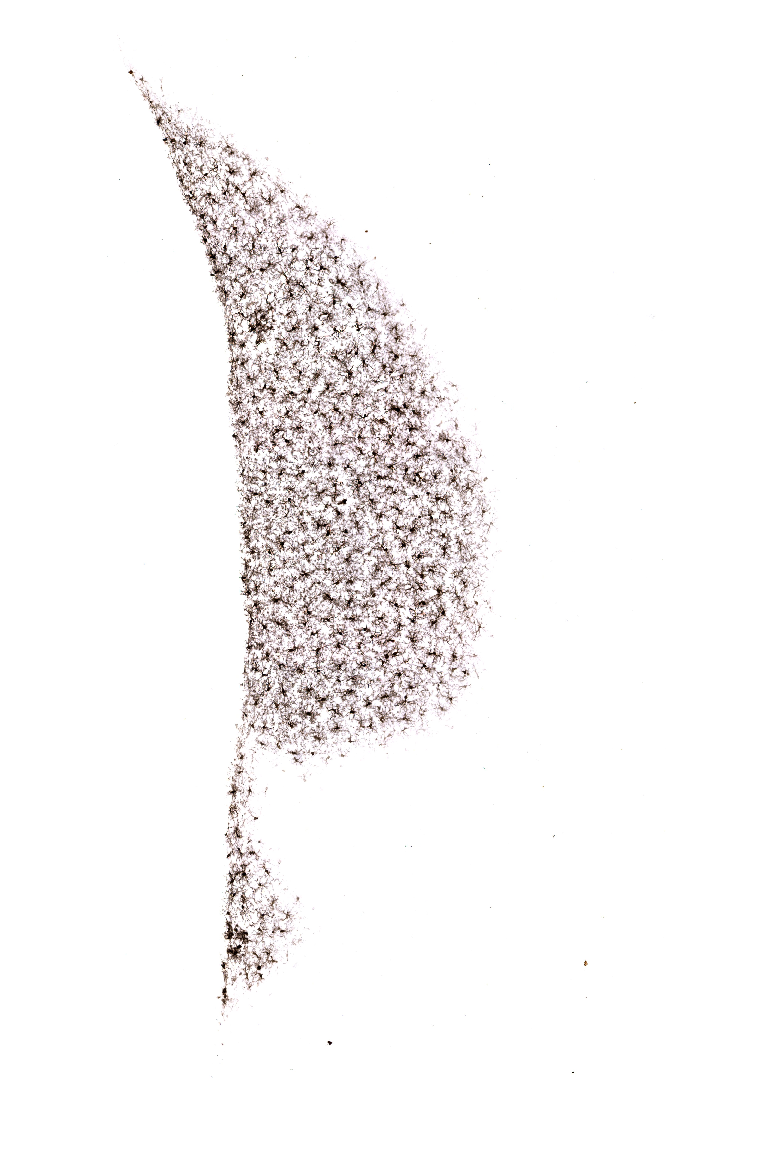

Elapsed time is 0.577066 seconds.
Elapsed time is 0.087672 seconds.
Elapsed time is 0.136805 seconds.


% load and pre-process image
ii=1;
opts.keywords={dinfo{ii, 1}.filename_image};opts.Nkeywords={''};
DataSetInfo.sampleIdselect=DataSetInfo.sample_ID;
opts.save_test_maskrcnn=0;
opts.yolo_detection=0;
opts.load_yolo=0;
opts.unet_detection=0;
opts.save_test_yolo2unet=0;
opts.C50_prediction=0;
opts.load_UnetOneCell=0;
opts.save_train_path_case=3;
[data1]=microglia_detection(DataSetInfo,env,setp,opts);

save image for yolo and maskRCNN


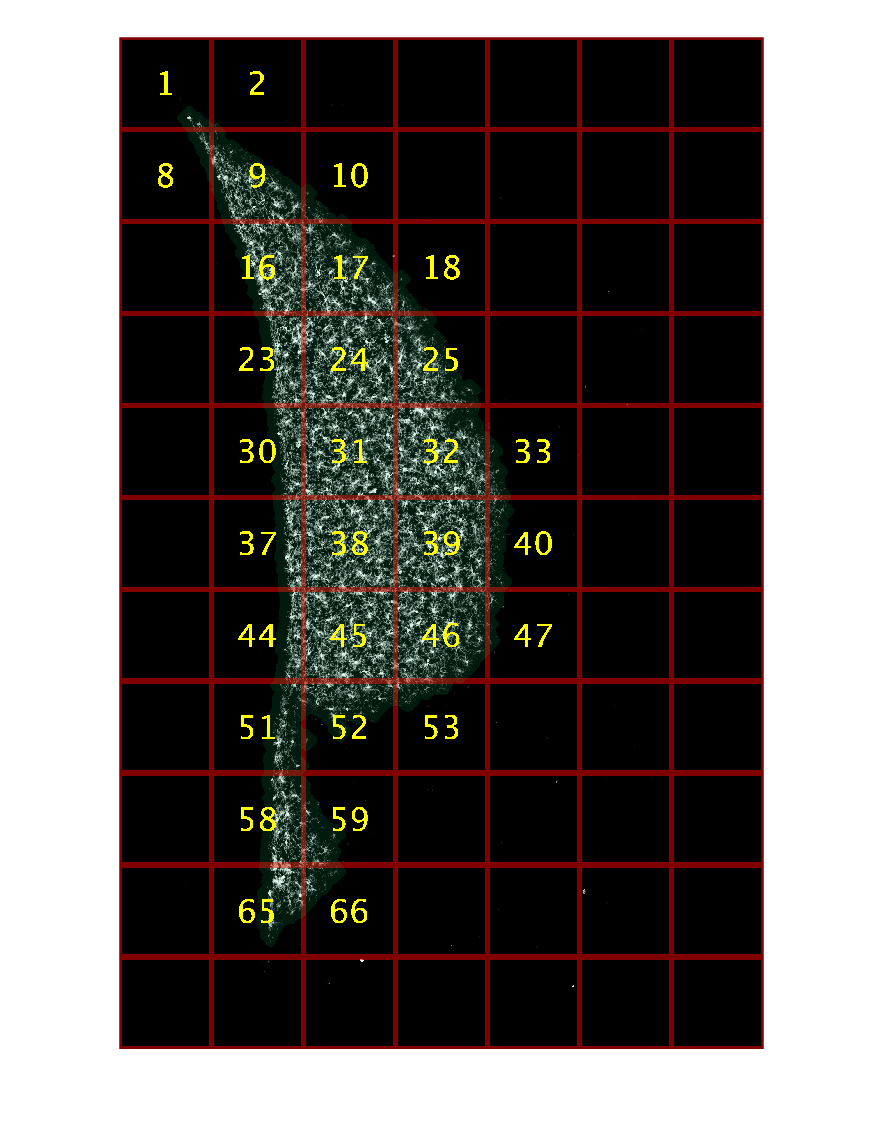

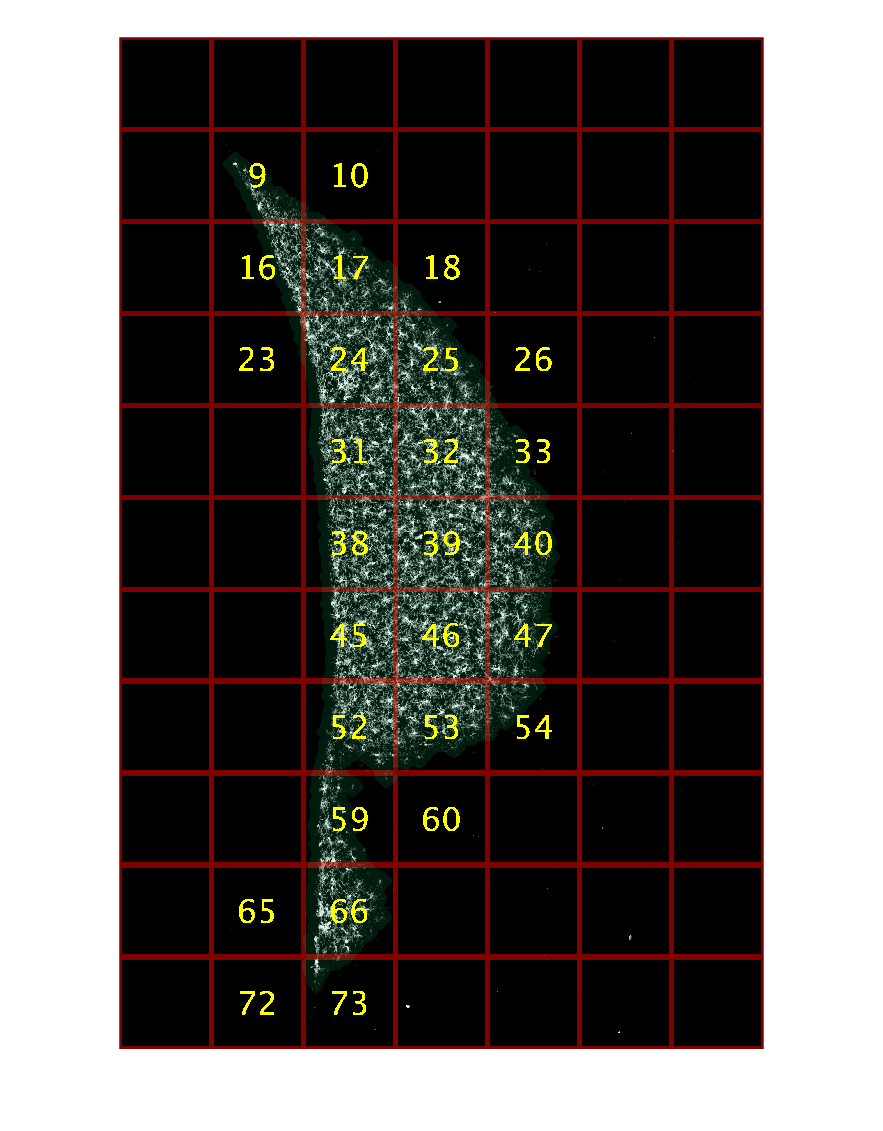

% save image for yolo and maskRCNN
    opts.keywords={dinfo{ii, 1}.filename_image};opts.Nkeywords={''};
    opts.yolo_folder_test={'noGt_im_512x512__test','noGt_im_512x512shift__test'};
    if isfield(env,'data_path0temp');data_path0temp=strrep(dinfo{ii}.filepath_image,env.data_path0,env.data_path0temp);else;data_path0temp=dinfo{ii}.filepath_image;end
    if ~isfolder([data_path0temp opts.yolo_folder_test{1}]);mkdir([data_path0temp opts.yolo_folder_test{1}]);end
    if length(dir([data_path0temp opts.yolo_folder_test{1}]))==2
        opts.save_test_maskrcnn=2;opts.yolo_detection=0;opts.load_yolo=0;opts.unet_detection=0;opts.C50_prediction=0;
        opts.load_UnetOneCell=0;
        fprintf('save image for yolo and maskRCNN\n');
        [data1]=microglia_detection(DataSetInfo,env,setp,opts,data1);
    end

% run yolo detection
if isfolder([data_path0temp 'noGt_im_512x512__result__YOLO_conf_50_100'])~=1
    fprintf('run yolo detection\n');
    opts.load_UnetOneCell=0;opts.cal_cell_props=0;opts.unet_detection=0;opts.dispfig1=0;
    opts.save_test_maskrcnn=0;opts.yolo_detection=1;opts.load_yolo=0;opts.save_train_path_case=3;
    [data1]=microglia_detection(DataSetInfo,env,setp,opts,data1);
end

run yolo detection


% load yolo detection
opts.save_test_maskrcnn=0;opts.yolo_detection=0;opts.load_yolo=1;opts.load_brainAtlas=0;
opts.load_UnetOneCell=0;opts.cal_cell_props=0;opts.C50_prediction=0;opts.load_cocoC50{1}='';
opts.unet_detection=0;opts.dispfig1=1;
opts.yolo_folder_test={'noGt_im_512x512__test','noGt_im_512x512shift__test'};
fprintf('load yolo detection\n');

load yolo detection


load noGt_im_512x512__test
load noGt_im_512x512__result__YOLO_conf_50_100
load noGt_im_512x512shift__test
load noGt_im_512x512shift__result__YOLO_conf_50_100
load noGt_im_512x512__result__YOLO_conf_50_100_M


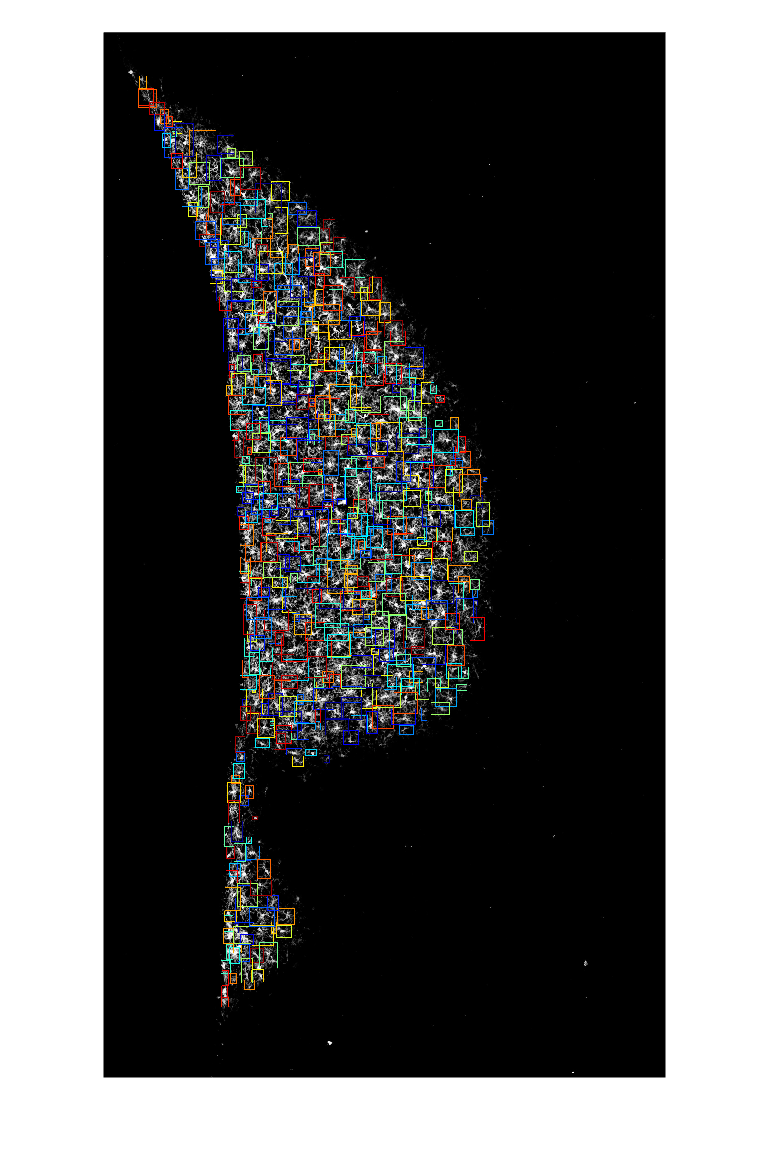

[data1]=microglia_detection(DataSetInfo,env,setp,opts,data1);

% save image for UNET
if isfolder([data_path0temp 'noGt_im_512x512__result__YOLO_conf_50_100'])
    if length(dir([data_path0temp 'noGt_im_512x512__result__YOLO_conf_50_100']))>2
        if isfolder([data_path0temp 'Yolo512_SS3_256x256__test'])~=1
            opts.yolo_detection=0;opts.load_yolo=1;opts.save_test_yolo2unet=1;opts.dispfig1=0; 
            opts.save_train_path_case=3;opts.save_matlabss=3; % for matlab smentatic segmentation
            fprintf('save image for UNET\n');
            [data1]=microglia_detection(DataSetInfo,env,setp,opts,data1);
        end
    end
end

save image for UNET


%% Unet detection
if length(dir([data_path0temp 'Yolo512_Unet_256x256__result__netC4b1']))<=2
    opts.load_yolo=1;opts.load_UnetOneCell=0;opts.cal_cell_props=0;opts.dispfig1=0;
    opts.save_matlabss=0;opts.load_yolo=0;opts.save_test_yolo2unet=0;
    opts.unet_detection='matlabss3';opts.unet_name='netC4';
    opts.unet_file=[env.matlab_path 'unetpt' filesep 'netC4_Unety_dice_nVep10.mat'];
    opts.unet_results_folderE=[opts.unet_name 'b1']; %ext of unet result folder
    [data1]=microglia_detection(DataSetInfo,env,setp,opts,data1);
end

Running semantic segmentation network
-------------------------------------
* Processed 534 images.



%% load Unet results and calculate cell properties
opts.unet_detection=''; % turn off unet detection
opts.dispfig1=1; 
opts.save_coco=1;opts.load_cocoC50{1}='';
opts.load_yolo=1;opts.load_UnetOneCell=1;opts.cal_cell_props=0;opts.category_update=1;opts.save_coco_selected_prop=1;
opts.unet_name='netC4';opts.unet_results_folderE=[opts.unet_name 'b1'];
fprintf('load UNET result\n');

load UNET result


save coco: Yolo512_SS3_256x256__test
load: Yolo512_Unet_256x256__result__netC4b1
save coco - Yolo512_Unet_256x256__result__netC4b1


bbm = 500

Elapsed time is 53.419578 seconds.
Elapsed time is 0.978751 seconds.
load or save coco:Yolo512_Unet_256x256__result__netC4b1_ML


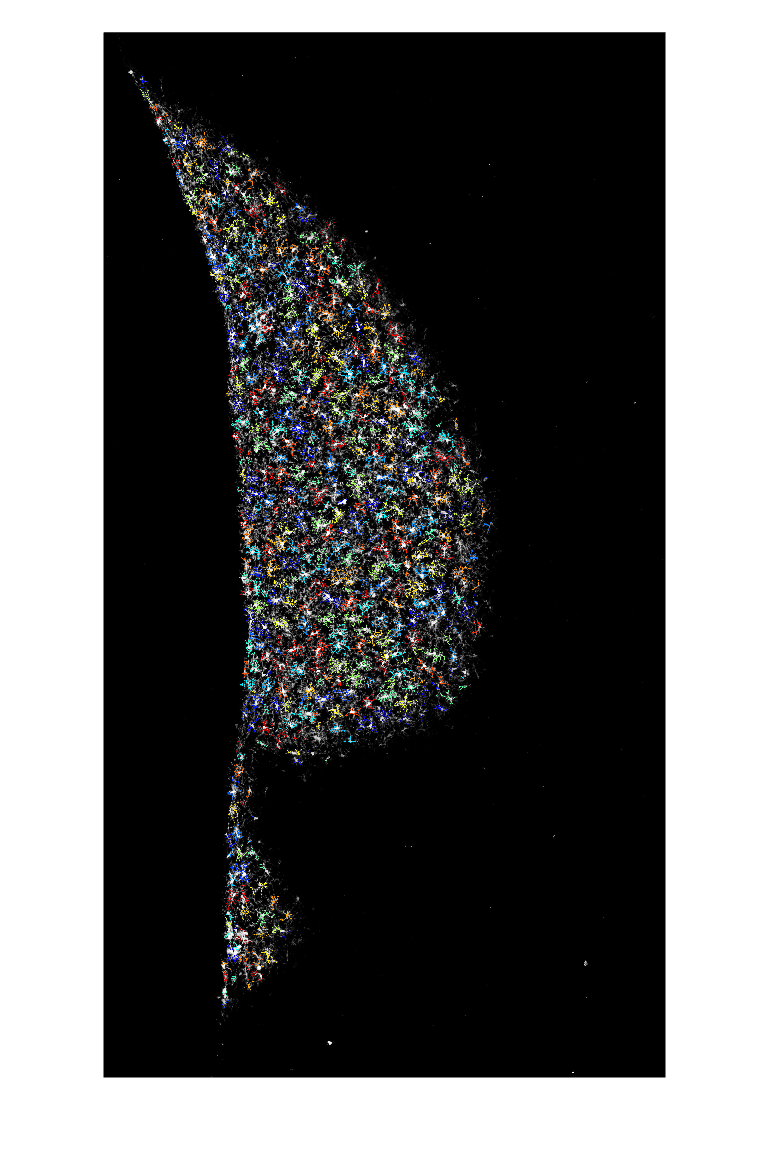

[data1]=microglia_detection(DataSetInfo,env,setp,opts,data1);

flag.cal_cell_props=1;opts.dispfig1=0; 
% calculate cell properties
if flag.cal_cell_props==1
    opts.unet_detection=''; % turn off unet detection
    opts.save_coco=1;opts.load_cocoC50{1}='';
    opts.load_yolo=1;opts.load_UnetOneCell=1;opts.cal_cell_props=1;opts.category_update=1;opts.save_coco_selected_prop=1;
    fprintf('calculate cell properties\n');
    [data1]=microglia_detection(DataSetInfo,env,setp,opts,data1);
end

calculate cell properties


Calculate/load mask properties for Yolo512_Unet_256x256__result__netC4b1_ML 
Loading and preparing annotations... Loading and preparing annotations... Elapsed time is 364.623591 seconds.


bcp = 514

Loading and preparing annotations... DONE (t=0.05s).
Loading and preparing annotations... DONE (t=0.03s).


% run C50 classification and output parameter table
opts.load_cocoC50={'C50v1'};opts.regp_verC50={'regp11'};opts.save_coco_selected_prop=0;
nn=1;opts.dispfig1=0; 
if exist([data1{nn, 1}.info.filepath_image  data1{nn, 1}.info.foldername_coco{1} filesep data1{nn, 1}.info.filename_image(1:end-4) '__Yolo512_Unet_256x256__result__' opts.unet_results_folderE '_ML__V04regp11__' opts.load_cocoC50{1} '.json'],'file')
    opts.C50_prediction=0;% load C50 results
else
    opts.C50_prediction=1;
end
opts.optable={'Yolo512_Unet_256x256__result__netC4b1_ML'};
opts.update_results=1;opts.update_yoloscore=0;
fprintf('C50 classifier prediction\n');

C50 classifier prediction


[data1,table1{1}]=microglia_detection(DataSetInfo,env,setp,opts, data1);opts.C50_prediction=0;

Loading and preparing annotations... DONE (t=0.04s).


nc = 1

Loading and preparing annotations... DONE (t=0.03s).
Loading and preparing annotations... DONE (t=0.03s).
Loading and preparing annotations... DONE (t=0.03s).


## **Results**

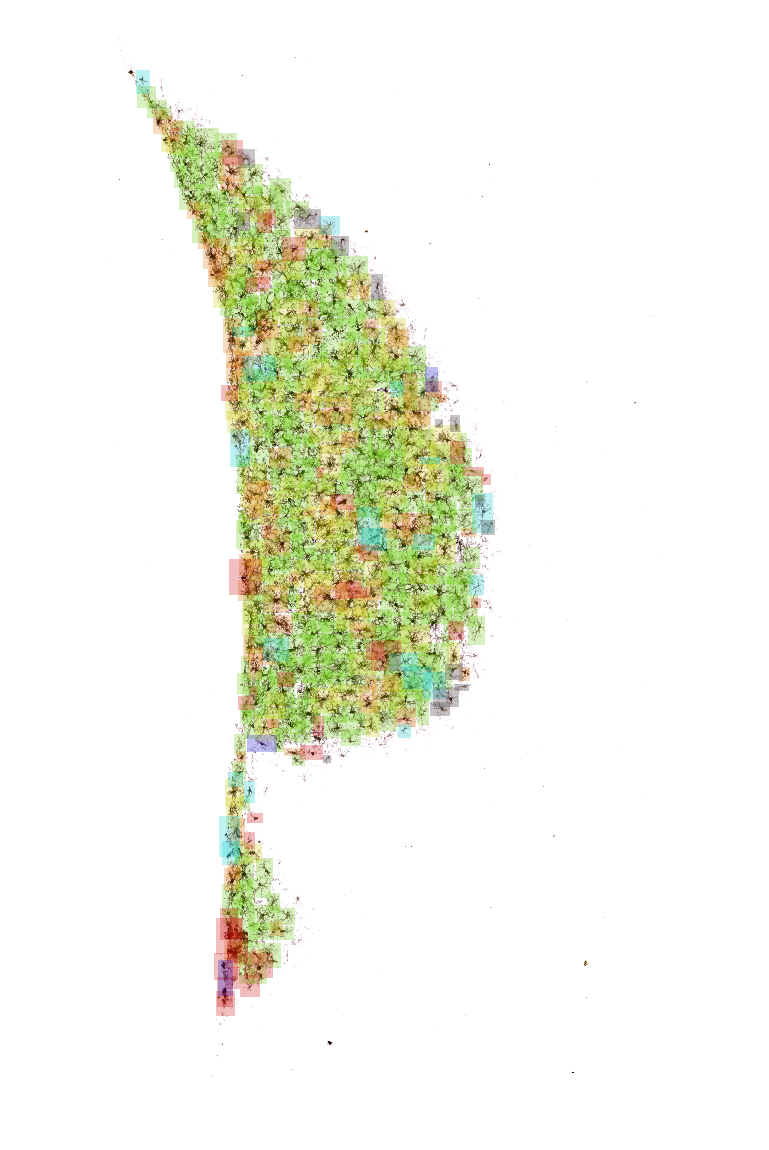

% set threshold of Cell Area > 30um to remove debris
threshold_para.name={'CArea'};threshold_para.min={30};threshold_para.max={''}; %set threshold to get index in index_thTable_v01
disp.type_name0={'R';'H';'B';'A';'RD';'HR';};
disp.box_ratio1=[1.4, 1.4, 1.4, 2.5, 2, 2.5, 1.4];
disp.box_ratio2=[ 1   1  1  1  1  1 1];
disp.label_name=    {'R';            'H';            'B';        'A';       'RD';          'HR';   'badFM'};
disp.cmap_label=    {[102,204,0], [204 204 0],[220 112 0], [204 0 0], [0 210 210],[0  0 204],   [102 102 102]};
disp.cmap_label{7}=[255 255 255];
disp.opacity=[0.25 0.25 0.25 0.25 0.25 0.25 0.25];
disp.name_resL=-1; %for output image resolution
disp.th_FM=600;
if isfield(data1{nn,1}.info,'filename_orig')
    imsavefilename=data1{nn,1}.info.filename_orig;
else
    imsavefilename=data1{nn,1}.info.filename_image;
end

[ind,dataA_bar]=index_thTable_v01(table1{1},threshold_para,{data1{nn,2}(1:3)},disp);
[data_Cim2d,indLable,bardata]=insertLabelbox2imagefromTable(data1{nn, 1}.im0gray,table1{1},data1{1}.info,ind,disp);
imFs2=data_Cim2d.cboxA_im0L(fix(data1{nn,1}.zeropadding_sizeext(1)/2)+1:size(data1{nn, 1}.im0gray,1)-fix(data1{nn,1}.zeropadding_sizeext(1)/2),fix(data1{nn,1}.zeropadding_sizeext(2)/2)+1:size(data1{nn, 1}.im0gray,2)-fix(data1{nn,1}.zeropadding_sizeext(2)/2),:);
if DataSetInfo.im_pixel_size~=0.464;imFs2=imresize(imFs2,size(data1{nn,1}.im0orig,1:2));end
if ~isfolder([data1{nn,1}.info.filepath_image 'results' filesep 'Mmaps']);
    mkdir([data1{nn,1}.info.filepath_image 'results' filesep 'Mmaps']);end
if ~exist([data1{nn,1}.info.filepath_image 'results' filesep 'Mmaps' filesep imsavefilename(1:end-4) '_Morph_FM' num2str(disp.th_FM) '_gray.jpg'],'file')
    if opts.save_imsplit~=0
        imwriteSplit(imFs2,[data1{nn,1}.info.filepath_image 'results' filesep 'Mmaps' filesep  imsavefilename(1:end-4) '_Morph_FM' num2str(disp.th_FM) '_gray.jpg'],opts.save_imsplit);
    else
        imwrite(imFs2,[data1{nn,1}.info.filepath_image 'results' filesep 'Mmaps' filesep  imsavefilename(1:end-4) '_Morph_FM' num2str(disp.th_FM) '_gray.jpg']);
    end
end
disp.cmap_label{7}=[30 30 30];
[data_Cim2d,indLable,bardata]=insertLabelbox2imagefromTable(data1{nn, 1}.im0,table1{1},data1{1}.info,ind,disp);

imFs2=data_Cim2d.cboxA_im0L(fix(data1{nn,1}.zeropadding_sizeext(1)/2)+1:size(data1{nn, 1}.im0,1)-fix(data1{nn,1}.zeropadding_sizeext(1)/2),fix(data1{nn,1}.zeropadding_sizeext(2)/2)+1:size(data1{nn, 1}.im0,2)-fix(data1{nn,1}.zeropadding_sizeext(2)/2),:);

if DataSetInfo.im_pixel_size~=0.464;imFs2=imresize(imFs2,size(data1{nn,1}.im0orig,1:2));end
if ~exist([data1{nn,1}.info.filepath_image 'results' filesep 'Mmaps' filesep imsavefilename(1:end-4) '_Morph_FM' num2str(disp.th_FM) '_rgb.jpg'],'file')
    if opts.save_imsplit~=0
        imwriteSplit(imFs2,[data1{nn,1}.info.filepath_image 'results' filesep 'Mmaps' filesep  imsavefilename(1:end-4) '_Morph_FM' num2str(disp.th_FM) '_rgb.jpg'],opts.save_imsplit);
    else
        imwrite(imFs2,[data1{nn,1}.info.filepath_image 'results' filesep 'Mmaps' filesep  imsavefilename(1:end-4) '_Morph_FM' num2str(disp.th_FM) '_rgb.jpg']);
    end
end
figure(1);imshow(imFs2)

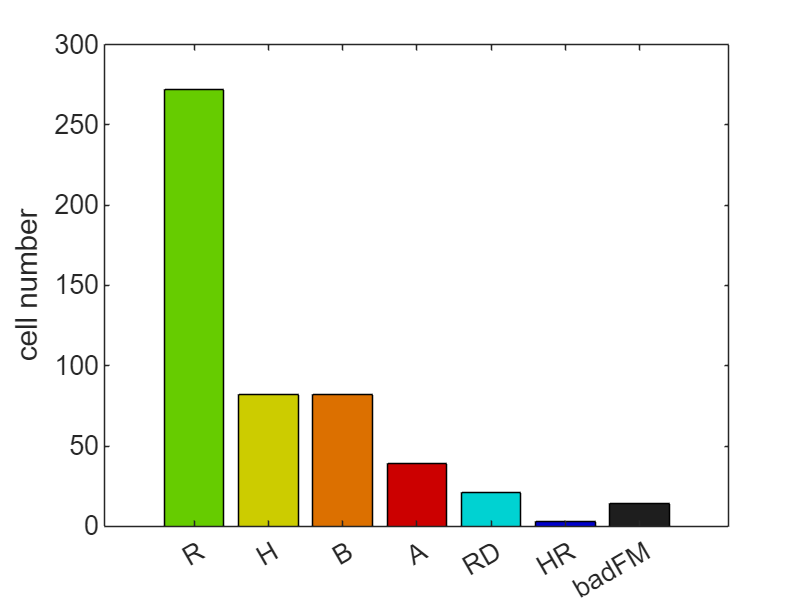

%% cell numbers
figure(2);set(gcf,'color','w')
b=bar(bardata,'FaceColor','flat');
for k = 1:length(bardata)
    b.CData(k,:) = disp.cmap_label{k}/255;
end;ylabel('cell number');
xticklabels(disp.label_name);set(gca,'FontSize',14)

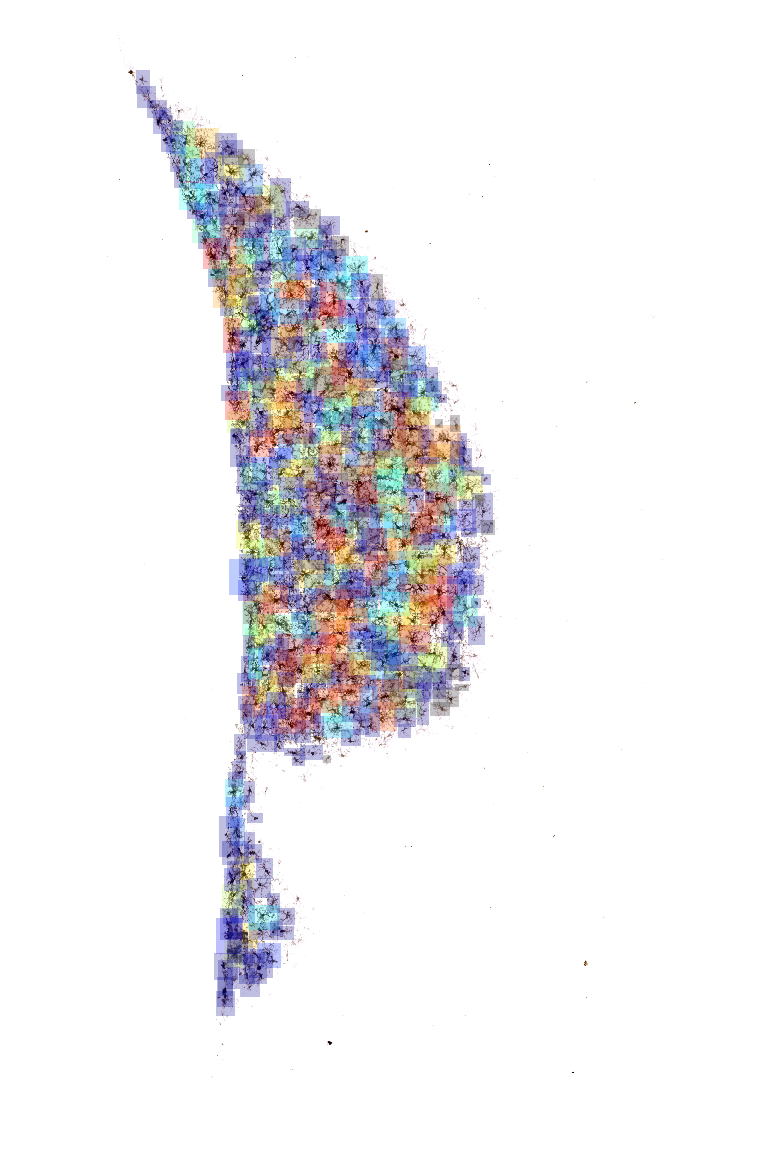


%% save MorphoMetric Maps
disp.metric_name='CArea'; % see columns in table1
ydata1=table1{1}.(disp.metric_name);
clim1=[quantile(ydata1,0.5) quantile(ydata1,0.95)]; % 5-95%
im2=morphometricMap(data1{1}.im0,clim1,'jet',table1{1},ind,disp);
im2=im2(fix(data1{nn,1}.zeropadding_sizeext(1)/2)+1:size(data1{nn, 1}.im0,1)-fix(data1{nn,1}.zeropadding_sizeext(1)/2),fix(data1{nn,1}.zeropadding_sizeext(2)/2)+1:size(data1{nn, 1}.im0,2)-fix(data1{nn,1}.zeropadding_sizeext(2)/2),:);
if DataSetInfo.im_pixel_size~=0.464;im2=imresize(im2,size(data1{nn,1}.im0orig,1:2));end
if ~exist([data1{nn,1}.info.filepath_image 'results' filesep 'Mmaps' filesep imsavefilename(1:end-4) '_' disp.metric_name '_FM' num2str(disp.th_FM) '_rgb.jpg'],'file')
    if opts.save_imsplit~=0
        imwriteSplit(im2,[data1{nn,1}.info.filepath_image 'results' filesep 'Mmaps' filesep  imsavefilename(1:end-4) '_' disp.metric_name '_FM' num2str(disp.th_FM) '_rgb.jpg'],opts.save_imsplit);
    else
        imwrite(im2,[data1{nn,1}.info.filepath_image 'results' filesep 'Mmaps' filesep  imsavefilename(1:end-4) '_' disp.metric_name '_FM' num2str(disp.th_FM) '_rgb.jpg']);
    end
end
figure(3);imshow(im2)